%Inputs
clc
clear

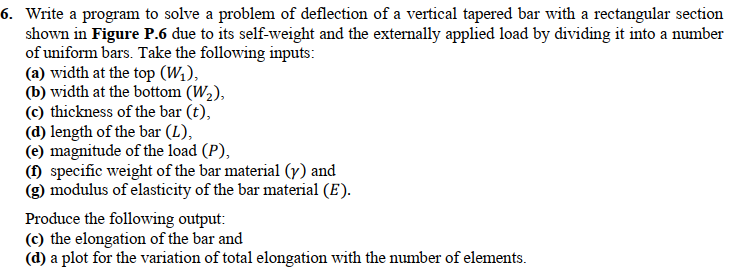

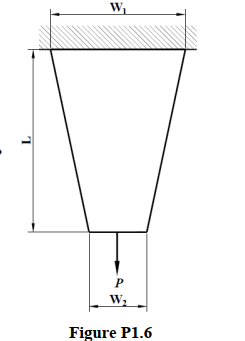

format long
% L=input("Enter the lenght in meter: ")
% W1=input("Enter the width at the top W1 in meter: ")
% W2=input("Enter the width at the bottom W2 in meter: ")
% t=input("Enter the thickness of the bar in m: ")
% g=input("Enter the specific weight of the bar material in N/m^3: ")
% E=input("Enter the elastic modulus in N/m^2: ")
% P=input("Enter the force applied in N: ")
L=0.5

L =    0.500000000000000


W1=0.05

W1 =    0.050000000000000


W2=0.025

W2 =    0.025000000000000


t=0.015

t =    0.015000000000000


g=78600

g =        78600


E=210e9

E =      2.100000000000000e+11


P=50000

P =        50000


Exact Value Calculation:

ev= g*(L^2)/(2*E)+P*L*log(W1/W2)/(E*t*(W1-W2))

ev =      2.200935097015699e-04


Input the number of elements for finding the deflection using FEM

e=input("Enter the number of elements: ")

e =     20


Loop for finding the value of x,H and A required for each element

for n=1:e
    for m=1:1+n % i+1 points needed for making i elemnts
        y(m)=(m-1)*L/n;  % for 1 element only 2 points needed at y=0 and y=L
        W(m)=W2-(W2-W1)*y(m)/L; % finds width according to the position at y(m)
        A(m)=W(m)*t; % Area at a given point where width is W(m) to find the average of area
    end

Area average

for j=1:n
    Aa(j)=(A(j)+A(j+1))/2;
end

Taking initial deformation =0 and taking average of area at two ends for area of the element, we have,

td(n)=0;
for z=1:n
    weight_below=0;
        for i=1:z-1
            weight_below=weight_below+g*Aa(i)*(L/n);
        end
    td(n)=td(n)+weight_below*(L/n)/(Aa(z)*E)+P*L/(A(z)*E*n);
end 
error_percentage(n)=(td(n)-ev)*100/ev;
end
fprintf("The total deformation is %f. \n",td(n))

The total deformation is 0.000224. 


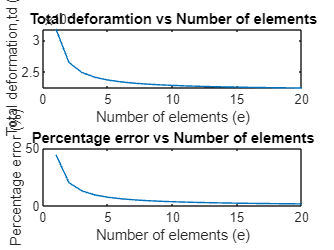

subplot(2,1,1)
plot(1:e,td)
xlabel("Number of elements (e)")
ylabel("Total deformation,td (m)")
title("Total deforamtion vs Number of elements")
subplot(2,1,2)
plot(1:e,error_percentage)
xlabel("Number of elements (e)")
ylabel("Percentage error (%)")
title("Percentage error vs Number of elements")

deformation=transpose(td);
error=transpose(error_percentage);
table=[deformation,error];
xlswrite('Assignment1_6.xls',table);


